clear all
% 100 logarthmically spaced points between 10^0 and 10^-20
h = logspace(-20,0,100);

x0 = pi/4;

% write the true value of the derviavtive of tan(x) evaluated at x0
TrueDeriv = sec(x0)^2;   

% compute the numerical deriative of the given function using eq. (2.2) of assignment
% for all the values of h
dydx_approx =(tan(x0+h)-tan(x0-h))./(2*h)

dydx_approx =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    4.0269    2.5290    2.8589    2.5935    2.1299    1.9671    2.0261    2.0173    2.0466    2.0198    2.0065    2.0133    2.0043    2.0052    2.0008    2.0017    2.0005    2.0006    1.9999    2.0000    2.0002    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000



abserror=abs(TrueDeriv-dydx_approx)

abserror =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0269    0.5290    0.8589    0.5935    0.1299    0.0329    0.0261    0.0173    0.0466    0.0198    0.0065    0.0133    0.0043    0.0052    0.0008    0.0017    0.0005    0.0006    0.0001    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000




% compute the truncation error using the expression you obtained in Question 2 part a)  
truncation_error = (4*sec(x0)^2*tan(x0)^2+2*sec(x0)^4)*(h.*h)/factorial(3) 

truncation_error =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


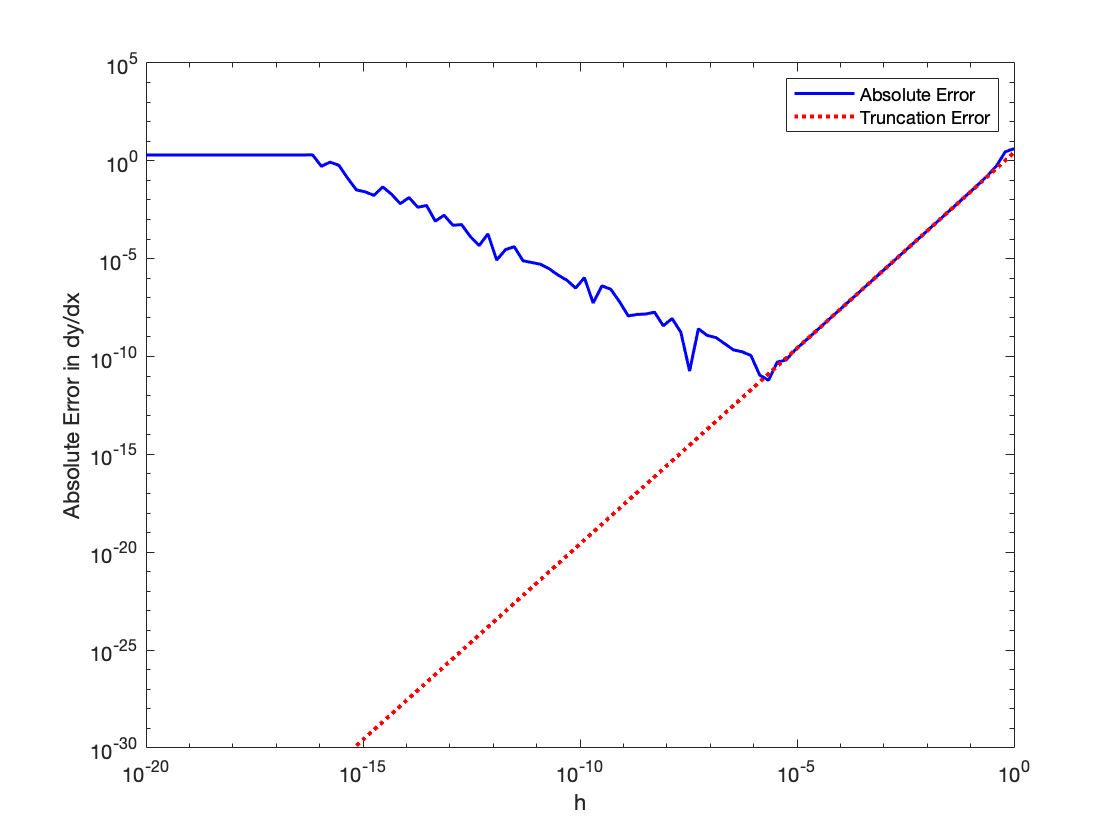



% compute the absolute error . It is already done for you.
% Absolute error is the difference between the True value of derivative and 
% estimated value of the derivative.
Absolute_error = abs(TrueDeriv - dydx_approx); 

clf
figure(1)
loglog(h,Absolute_error,'b','Linewidth',1.5)
hold on
figure(1)
loglog(h(25:100),truncation_error(25:100),'r:','Linewidth',2)

xlabel('h')
ylabel('Absolute Error in dy/dx')

legend('Absolute Error','Truncation Error')

%TE = ((x0)*f"'(x0)*h^3)/factorial(3)
ymin=min(Absolute_error)

ymin = 6.1628e-12